# Hyperparameter tuning: how many neighbours?

Your colleague has shared some training and testing data with you. You can assume the data has been properly prepared and split:

clear all;
load('split.mat', 'train_examples', 'train_labels', 'test_examples', 'test_labels');

Use cross-validation on the training data to decide the best value of k for a k-Nearest Neighbours (k-NN) classifier, then use the winning value to train a k-NN classifier and evaluate its performance on the testing data. You should consider all odd values of k between 1 and 25 inclusive: 1, 3, 5, 7, 9, 11, 13, 15, 17, 19, 21, 23, 25.

Marks are available for:

- Writing an appropriate loop over the different values of k you are interested in [2 marks]

- Appropriate calls inside the loop to perform cross-validation on the training data using each value of k, and retain the relevant results [6 marks]

- Deciding on the best value for k based on a sensible quantitative comparison between the cross-validation results [4 marks]

- Training a final k-NN classifier with the winning value of k and evaluating its performance on the test data [4 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

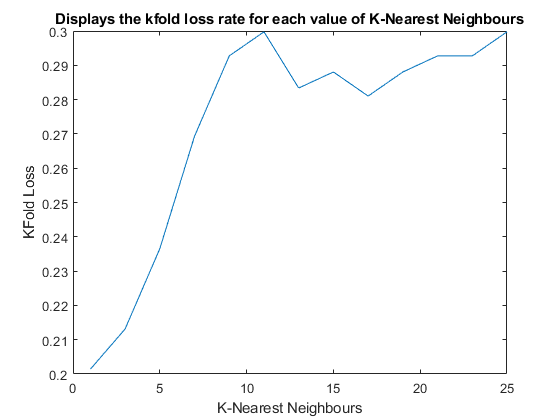

rng(1); % for repeatablity

% create array for storing the values of kfoldLoss:
KLoss = [];
% loop over k = 1-25 going up in 2:
for k=1:2:25
    % train the classifier with varying values of k-num neighbours with a kFold of 10:
    m = fitcknn(train_examples, train_labels, 'NumNeighbors', k, 'kFold', 10);
    % calculate the loss of each model and add to KLoss array list:
    KLoss(end+1) = kfoldLoss(m);
end
% plot the values of KfoldLoss against varying values of k-num neighbours
% to see the comparison of results:
k = 1:2:25;
plot(k, KLoss)
xlabel("K-Nearest Neighbours")
ylabel("KFold Loss")
title("Displays the kfold loss rate for each value of K-Nearest Neighbours")


% looking at the graph, k=1 is the best value for k as it has the lowest kfoldloss.
% A new kNN classifier is trained using k = 1:
finalM = fitcknn(train_examples, train_labels, 'NumNeighbors', 1);

% test classifier on the testing data:
predictions = predict(finalM, test_examples);
% create confusion matrix to show performance visually:
[c,order] = confusionmat(predictions, test_labels)

c =     77    16
     8    41


order = 2×1 categorical array
     Benign 
     Malignant 


% calculate the accuracy of the classifier:
accuracy = sum(diag(c)) / sum(c(:))

accuracy = 0.8310